clc
data=load('data.txt')

data =     20    25    60    70
    35    30    65   105
    40    34    75   135
    50    37    80   170


% Create a plot of the data
xt=(data);
yt=xt(:);
%n number or rows
%m number of columns 
[n,m]=size(data)

n = 4

m = 4

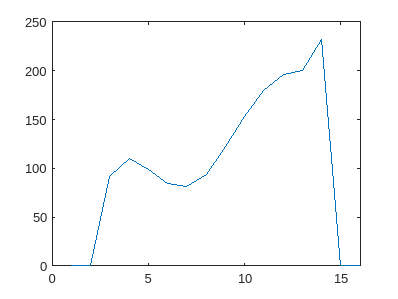

% k pair
% Define the parameters
k = 4;  % value of k
T=length(yt);
% Calculate the rolling mean using the formula
rolling_means=zeros(T,1);
for i=k:T-1
    rolling_means(i-1) = (0.5*(yt(i-k+1)))+ sum(yt(i-(k-2):i-1)) + (0.5*(yt(i))) / k;   
end
plot(rolling_means)

%rearange rolling means to match data dimension
MM=reshape(rolling_means,[n m])'

MM =          0         0   91.2500  110.6250
   98.7500   84.2500   81.1250   93.5000
  122.1250  152.8750  180.0000  196.2500
  200.6250  231.8750         0         0


% division element by element
Sj=data./MM

Sj =        Inf       Inf    0.6575    0.6328
    0.3544    0.3561    0.8012    1.1230
    0.3275    0.2224    0.4167    0.6879
    0.2492    0.1596       Inf       Inf


B1=zeros(1,m)

B1 =      0     0     0     0


for j=1:m
    if j<=m-2
        B1(:,j)=[sum(Sj(2:end,j))]/(n-1)
    else
        B1(:,j)=[sum(Sj(1:end-1,j))]/(n-1)
    end
end

B1 =     0.3104         0         0         0


B1 =     0.3104    0.2460         0         0


B1 =     0.3104    0.2460    0.6251         0


B1 =     0.3104    0.2460    0.6251    0.8146


%moyenne de B
sjprim=mean(B1);
sj=B1-sjprim;
sjrep=repmat(sj',m,1);
sjj=sjrep(:);
xijprim=yt-sjrep';

%ajustement modele
t=1:T;
p1=polyfit(t,xijprim,1); %ajuster un polynoome
% p contient les coefficients en puissance decroissante
yfit = polyval(p1,t)
a=p1(:,1);
b=p1(:,2);
ychapeau=yfit'+sjj;
% ychapeau(:,:)= (trim(:,:)-sjrep(:,:));

Error using polyfit
The first two inputs must have the same number of elements.